# Geostatistika 06

Vytvoříme si testovací data funkce sinus ovšem s náhodnými odchylkami,

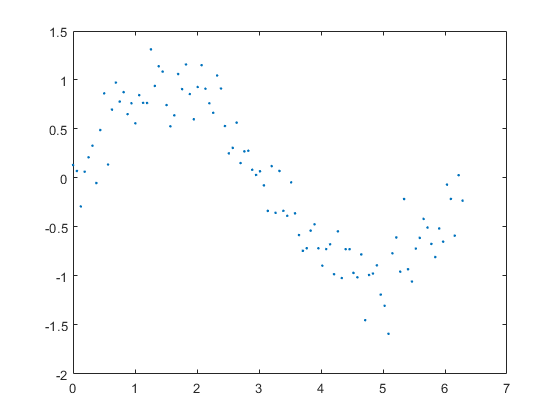

xd = [0:100] / 100 * 2 * pi;
zd = sin(xd) + randn(1, 101) * 0.25;

plot(xd, zd, '.')
hold off

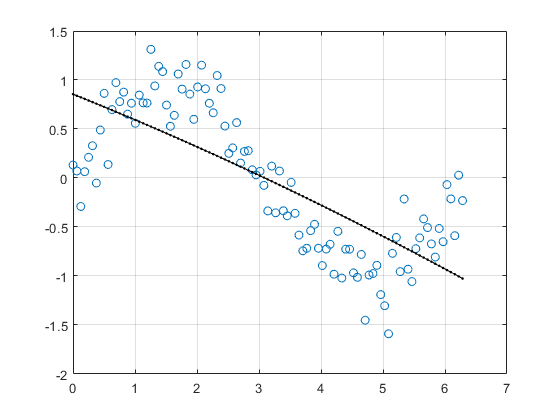


polynom_LSQ(xd, zd, xd)

**Úloha 1.    **Vykreslete graf funkce 𝑓(𝑑) = exp (−(𝑑/ℎ)2)) pro ℎ =1, 2, 3 v intervalu 𝑑 ∈ 〈−10,10〉 a obrázek vložte do elaborátu.

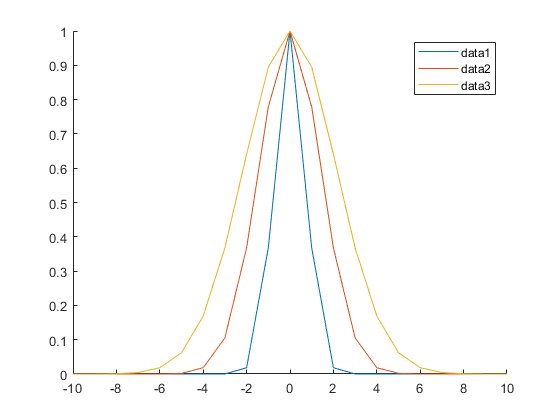


figure;
hold on;

for h = 1:3
    ds = -10:10;
    zs = zeros(1, 20);
    for i = 1:length(ds)
        zs(i) = exp(-(ds(i)/h)^2);  % Gaussovské váhy.
    end
    plot(ds, zs);
    legend();
end    

hold off;

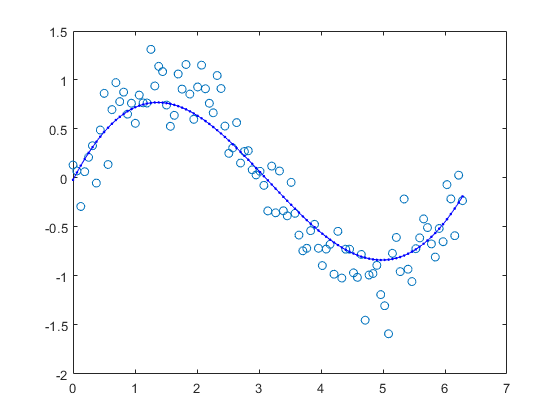

polynom_lokalni(xd, zd, xd, 2) % h volím 2

**Úloha 2.    **Funkci polynom_lokalni uložte jako primka_lokalni a upravte její kód tak, aby se lokálně prokládala přímka. Vhodným nastavením parametru lokálnosti se pokuste dosáhnout uspokojivého proložení. Kód i obrázek vložte do elaborátu.

%primka_lokalni(xd, zd, zd,1)

**Úloha 3.**

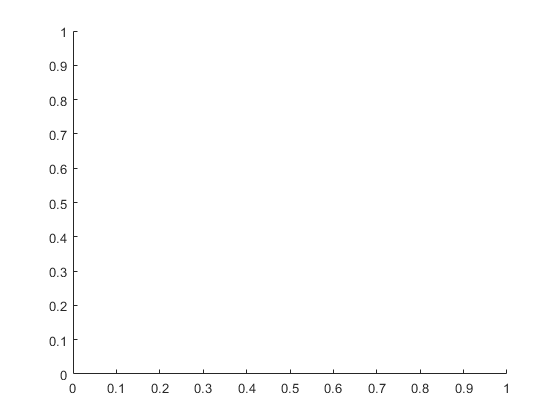

figure;
hold on;


for h = 1:1
    ds = -1.5:1.5;
    zs = zeros(1, 20);
    for i = 1:length(ds)
        d = ds(i);
        if d < h
            zs(i) = (1 - (abs(d)/h)^3)^3;  % tri-kubické váhy.
        end
    end
    plot(ds, zs);
    legend();
end    

ans = 4

Error using plot
Vectors must be the same length.


hold off;